# Australian Temperatures

This code reads the temperature data.

fid  = fopen("2014temps.txt");
% The first line contains the station number and the number of temperature readings.
s = fgetl(fid)

s = '941190 12'

s = split(s)

s = 2×1 cell array
    {'941190'}
    {'12'    }


nlines = str2double(s{2})

nlines = 12

% The second line contains the time for each column.
headers = split(fgetl(fid))

headers = 16×1 cell array
    {'020000'}
    {'023000'}
    {'050000'}
    {'053000'}
    {'080000'}
    {'083000'}
    {'110000'}
    {'113000'}
    {'140000'}
    {'143000'}
    {'170000'}
    {'173000'}
    {'200000'}
    {'203000'}
    {'230000'}
    {'233000'}


## Task 1

The script processes the first two lines of `2014``temps.txt` using the code from the last lesson.

The first block of data has a lot of columns. You could manually type out `textscan`'s format specification, but this is prone to typing mistakes. More importantly, notice that each block of data has a different number of columns.

If you want to create a script that reads each block of data, it's cleaner to programmatically create the format specification string.

You can use the `repmat` function to repeat the floating-point specification. For example, this code creates a specification for 10 text arrays in a row.

`x` `=` `repmat``(``'%q'``,``1``,``10``)`

**TASK1**

Save the number of elements in `headers` to a variable name `ncols`.

Use `ncols` to create a format specification string for the floating point (`'%f'`) columns in the data block. Name the specification string `fmtStr`.

**Hint1**

Use the `numel` function with `headers` to find the number of columns. `ncols` should be your third input to `repmat`. You need to use character vectors (`'`) with `repmat`.

ncols = numel(headers)

ncols = 16

fmtStr = repmat('%f',1,ncols)

fmtStr = '%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f'

## Task 2

Now that you've got the correct number of numeric columns, you just need to add the specification for the `datetime`. Recall that each line begins with a datetime with the format `yyyyMMdd`. You can use a datetime format in the specification string:

`'%{format}D'`

**TASK2**

Append the datetime specification to the beginning of `fmtStr`. Then read in the data block using `fid`, `fmtStr`, and `nlines`.

Save the data to a variable named `stninfo`. 

**Hint2**

If you're using character vectors, the second input to `textscan` should be `[``'%{yyyyMMdd}D'` `fmtStr``]`. 

stninfo = textscan(fid,[ '%{yyyyMMdd}D' fmtStr ],nlines)

stninfo = 1×17 cell array
    {12×1 datetime}    {12×1 double}    {12×1 double}    {12×1 double}    {12×1 double}    {12×1 double}    {12×1 double}    {12×1 double}    {12×1 double}    {12×1 double}    {12×1 double}    {12×1 double}    {12×1 double}    {12×1 double}    {12×1 double}    {12×1 double}    {12×1 double}


fclose(fid);

## Task 3

Once you get the data out of the file, you might want to store it in a more appropriate data type. You can create a timetable with the `timetable` function.

To create a `table` or a `timetable`, from a cell array where each cell is a table variable, you should make a comma-separated list with `{``:``}`:

`stninfo``{``:``}`

The variable names for your table are stored in `headers`. These can be set with the option `'VariableNames'`. Note that the `'VariableNames'` option must use single quotes (`' '`).

**TASK3**

Create a timetable named `stn` using `stninfo``{``:``}` as the variables and `headers` as the variable names.

**Hint3**

Use `stninfo``{``:``}` as the first input to the `timetable` function.

stn = timetable(stninfo{:},'VariableNames',headers)

stn = 12×16 timetable
      Time      020000    023000    050000    053000    080000    083000    110000    113000    140000    143000    170000    173000    200000    203000    230000    233000
    ________    ______    ______    ______    ______    ______    ______    ______    ______    ______    ______    ______    ______    ______    ______    ______    ______

    20140101     32.5      32.5     

You can view the temperate data for each time with the `stackedplot` function:

`stackedplot``(``stn``)`

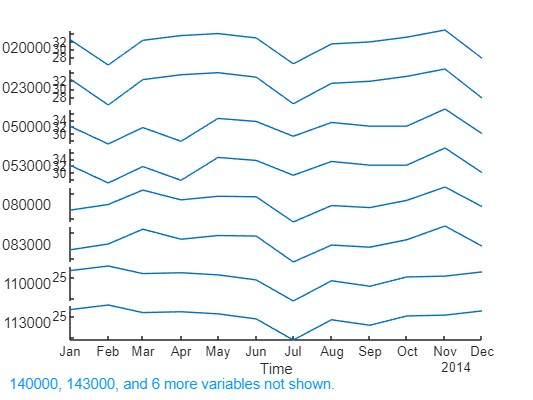

stackedplot(stn)